addpath(genpath('/datascience/projects/statisticallyfit/github/MATLAB/MatlabTutorial/AMTH250_NumericalMatlab/Numerical Analysis/Interpolation'))
addpath(genpath('/datascience/projects/statisticallyfit/github/MATLAB/MatlabTutorial/AMTH250_NumericalMatlab/Numerical Analysis/Least Squares'))

xData = [0 0.1 0.2 0.3 0.4 0.5 0.6 0.7 0.8 0.9 1];
yData = [0.05 0.19 -0.19 0.18 0.19 0.12 0.32 0.52 1.00 1.09 0.87];

Using the rref function to find the quadratic least squares solution

n = length(xData)

n =     11


xSum1 = sum(xData)

xSum1 =    5.500000000000000


xSum2 = sum(xData .^ 2)

xSum2 =    3.850000000000000


xSum3 = sum(xData .^ 3)

xSum3 =    3.025000000000000


xSum4 = sum(xData .^ 4)

xSum4 =    2.533300000000000


ySum = sum(yData)

ySum =    4.340000000000000


xySum = sum(xData .* yData)

xySum =    3.378000000000000


x2ySum = sum(xData.^2 .* yData)

x2ySum =    2.833800000000001


% set up the system
M = [n xSum1 xSum2; 
    xSum1 xSum2 xSum3;
    xSum2 xSum3 xSum4]

M =   11.000000000000000   5.500000000000000   3.850000000000000
   5.500000000000000   3.850000000000000   3.025000000000000
   3.850000000000000   3.025000000000000   2.533300000000000


b = [ySum, xySum, x2ySum]'

b =    4.340000000000000
   3.378000000000000
   2.833800000000001


consts = rref([M, b]);
consts = consts(:, end)

consts =    0.032167832167832
  -0.146573426573426
   1.244755244755245


% so the quadratic fit is: 

Quadratic fit is: y = 1.244755x^2 - 0.14657x + 0.032167

Now solve using homemade function

quad1 = nonlinearLeastSquares(xData, yData, {@(x) 1, @(x) x, @(x) x.^2})

$$quad1 = \frac{178\,x^{2}}{143}-\frac{524\,x}{3575}+\frac{23}{715}$$

vpa(quad1, 8)

$$ans = 1.2447552\,x^{2}-0.14657343\,x+0.032167832$$

quad2 = polyLeastSquares(xData, yData, 2)

$$quad2 = \frac{178\,x^{2}}{143}-\frac{524\,x}{3575}+\frac{23}{715}$$

Now solve using polyfit

coefs_quad = polyfit(xData, yData, 2)

coefs_quad =    1.244755244755245  -0.146573426573427   0.032167832167832


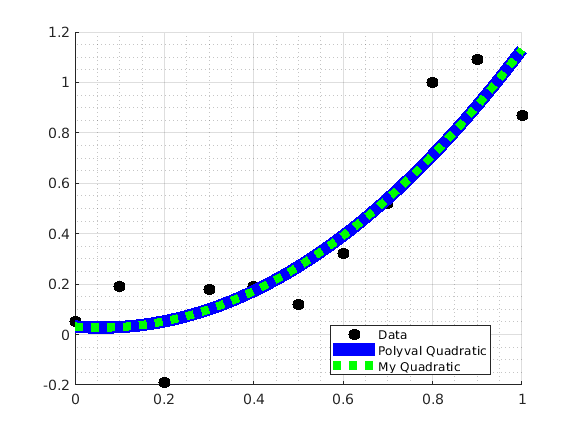

% plotting the data
xx = min(xData): 0.01: max(xData);
yy = polyval(coefs_quad, xx);

figure(1); clf; hold on; grid on; grid minor

% plot data
plot(xData, yData, 'k.', 'MarkerSize', 30) 
% plot polyval fits
plot(xx, yy, 'b-', 'LineWidth', 9) 
% plot my function
plot(xx, calcPoly(quad1, xx), 'g:', 'LineWidth', 6)

legend('Data', 'Polyval Quadratic', 'My Quadratic', 'Location', 'Best')

Question 5: 

% making a not a knot cubic spline
yy_spline = spline(xData, yData, xx);
% making an interpolation polynomial with polyfit and polyval
coefs_interp = polyfit(xData, yData, length(xData)-1);
yy_interp = polyval(coefs_interp, xx);
% the quadratic ols fit again (polyfit(xdata, ydata, 2)
yy_quadratic = polyval(coefs_quad, xx);

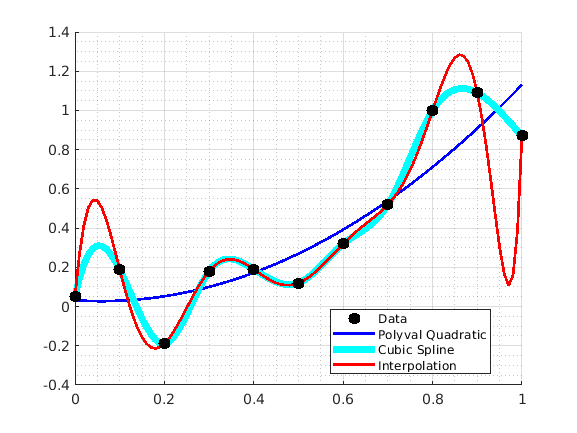

%plotting all the curves together


% plotting the data
figure(1); clf; hold on; grid on; grid minor

% plot polyval quadratic fits
h2 = plot(xx, yy_quadratic, 'b-', 'LineWidth', 2) ;
% plot cubic spline interpolations
h3 = plot(xx, yy_spline, 'c-', 'LineWidth', 5);
% plot the interpolations (lagrange)
h4 = plot(xx, yy_interp, 'r-', 'LineWidth', 2);
% plot data
h1 =plot(xData, yData, 'k.', 'MarkerSize', 30) ;

legend([h1, h2 h3 h4], {'Data', 'Polyval Quadratic', 'Cubic Spline', 'Interpolation'}, 'Location', 'Best')

For this data, the CUBIC SPLINE captures the fit better. The interpolation has too many curves and dips and the quadratic fit does not have enough curves/dips. 